# Taller 10

### 24/10/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 9 y 10*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

- **Otros recursos sobre manejo de MATLAB practicas básicas: ***https://matlabacademy.mathworks.com/es/*

*Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.*

#### Solución de los puntos propuestos

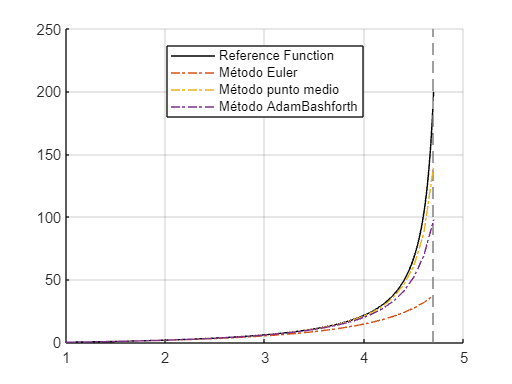

clear

f = @(t, y) 1 + y./t + (y ./ t).^2; % Reference ODE
a = 1; b = 4.7; ya = 0;
h = .1; M = (b - a)/h;

E = euler(f, a, b, ya, M);
mid = PVI_PuntoMedio(f, a, b, ya, M);
AB = PVI_AdamBashforthDos(f, a, b, ya, M);

t = E(:, 1);

y = @(t) t .* tan(log(t));          % Reference Solution

clf('reset')
hold on
fplot(y, [a, b], '-k')
plot(t, E(:, 2), '-.', 'MarkerSize', 12)
plot(t, mid(:, 2), '-.', 'MarkerSize', 12)
plot(t, AB(:, 2), '-.', 'MarkerSize', 12)
grid on
legend('Reference Function', 'Método Euler', ...
 'Método punto medio', 'Método AdamBashforth', ...
                            'Location','best')
hold off

#### Códigos / Rutinas planteadas

function  E = euler (f, a, b, ya, M)

% Entrada  - f funcion creada con @
%          - a y b son los extremos izquierdo y derecho
%          - ya es la condicion inicial  y(a)
%          - M es el numero de pasos
% Salida   - E = [T', Y'] donde T es el vector de abscisas y
%            Y es el vector de ordenadas

% METODOS NUMERICOS: Programas en Matlab (2004)
%   por John H. Mathews y Kurtis D. Fink
%
% Software complementario acompanando al texto:
%   METODOS NUMERICOS con Matlab

h = (b - a) / M;
Y = zeros(1, M+1);
T = a:h:b;
Y(1) = ya;

for  j = 1:M
   Y(j+1) = Y(j) + h * feval(f, T(j), Y(j));
end

E = [T', Y'];

end

function  mid = PVI_PuntoMedio(f, a, b, ya, M)

% Entrada  - f funcion creada con @
%          - a y b son los extremos izquierdo y derecho
%          - ya es la condicion inicial  y(a)
%          - M es el numero de pasos
% Salida   - mid = [T', Y'] donde T es el vector de abscisas y
%            Y es el vector de ordenadas

% METODOS NUMERICOS: Programas en Matlab (2004)
%   por John H. Mathews y Kurtis D. Fink
%
% Software complementario acompa~nando al texto:
%   METODOS NUMERICOS con Matlab

h = (b - a) / M;
Y = zeros(1, M+1);
T = a:h:b;
Y(1) = ya;  % w0 = a

for  j = 1:M
    ti = T(j) + h / 2;
    wi = Y(j) + h/2 * feval(f, T(j), Y(j));

    Y(j+1) = Y(j) + h * feval(f, ti, wi);    % wi+1 = ...
end

mid = [T', Y'];

end

function  AB = PVI_AdamBashforthDos(f, a, b, ya, M)

% Entrada  - f funcion creada con @
%          - a y b son los extremos izquierdo y derecho
%          - ya es la condicion inicial  y(a)
%          - M es el numero de pasos
% Salida   - AB = [T', Y'] donde T es el vector de abscisas y
%            Y es el vector de ordenadas

% METODOS NUMERICOS: Programas en Matlab (2004)
%   por John H. Mathews y Kurtis D. Fink
%
% Software complementario acompanando al texto:
%   METODOS NUMERICOS con Matlab

h = (b - a) / M;
Y = zeros(1, M+1);
T = a:h:b;
Y(1) = ya;
Y(2) = Y(1) + h * feval(f, T(1), Y(1));

for  j = 2:M
   Y(j+1) = Y(j) + h/2 * (3*feval(f, T(j), Y(j)) - ...
                 feval(f, T(j - 1), Y(j - 1)));
end

AB = [T', Y'];

end